syms xi et zt
assume([xi,et,zt], 'real')

P_Nodes = Node_Pyramid5()

$$P\_Nodes = \left(\begin{array}{ccc} -1 & -1 & 0\\ 1 & -1 & 0\\ 1 & 1 & 0\\ -1 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

SF = @SF_Pyramid5;

NN = size(P_Nodes,1);
DMat = sym(zeros(NN));
D0N = simplify(SF(xi,et,zt));
for i = 1:NN
    DMat(i,:) = SF(P_Nodes(i,1),P_Nodes(i,2),P_Nodes(i,3));
    if(any(isnan(double(DMat)),'all'))
        DMat(i,:) = limit(...
            subs(D0N,[xi,et],[P_Nodes(i,1),P_Nodes(i,2)]),...
            zt, P_Nodes(i,3));
        warning('using zeta''s limit')
    end
end

DMat

$$DMat = \left(\begin{array}{ccccc} 1 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

assert(logical(norm(DMat - eye(size(DMat))) == 0))


D0N = simplify(SF(xi,et,zt))

$$D0N = \left(\begin{array}{ccccc} -\frac{\left(\mathrm{et}+\mathrm{zt}-1\right)\,\left(\xi +\mathrm{zt}-1\right)}{4\,\left(\mathrm{zt}-1\right)} & \frac{\left(\mathrm{et}+\mathrm{zt}-1\right)\,\left(\xi -\mathrm{zt}+1\right)}{4\,\left(\mathrm{zt}-1\right)} & -\frac{\left(\mathrm{et}-\mathrm{zt}+1\right)\,\left(\xi -\mathrm{zt}+1\right)}{4\,\left(\mathrm{zt}-1\right)} & \frac{\left(\xi +\mathrm{zt}-1\right)\,\left(\mathrm{et}-\mathrm{zt}+1\right)}{4\,\left(\mathrm{zt}-1\right)} & \mathrm{zt} \end{array}\right)$$

D1N = simplify([diff(D0N,xi);diff(D0N,et);diff(D0N,zt)])

$$D1N = \begin{array}{l} \left(\begin{array}{ccccc} -\sigma_{4} & \sigma_{4} & -\sigma_{3} & \sigma_{3} & 0\\ -\sigma_{6} & \sigma_{5} & -\sigma_{5} & \sigma_{6} & 0\\ \sigma_{2} & \sigma_{1} & \sigma_{2} & \sigma_{1} & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{{\mathrm{zt}}^{2}-2\,\mathrm{zt}+\mathrm{et}\,\xi +1}{4\,{\left(\mathrm{zt}-1\right)}^{2}}\\ \sigma_{2}=\frac{-{\mathrm{zt}}^{2}+2\,\mathrm{zt}+\mathrm{et}\,\xi -1}{4\,{\left(\mathrm{zt}-1\right)}^{2}}\\ \sigma_{3}=\frac{\mathrm{et}-\mathrm{zt}+1}{4\,\left(\mathrm{zt}-1\right)}\\ \sigma_{4}=\frac{\mathrm{et}+\mathrm{zt}-1}{4\,\left(\mathrm{zt}-1\right)}\\ \sigma_{5}=\frac{\xi -\mathrm{zt}+1}{4\,\left(\mathrm{zt}-1\right)}\\ \sigma_{6}=\frac{\xi +\mathrm{zt}-1}{4\,\left(\mathrm{zt}-1\right)} \end{array}$$

% D0NCode = regexprep(fortran(D0N),...
%     ["D0N", "D([+-0])"], ...
%     ["v", "e$1"])
% D1NCode = regexprep(fortran(D1N),...
%     ["D1N", "D([+-0])"], ...
%     ["v", "e$1"])

D0NCode = regexprep(ccode(D0N),...
    ["D0N", "\[(\d+)\]\[(\d+)\]"],...
    ["v","($1,$2)"])

D0NCode =     '  v(0,0) = ((et+zt-1.0)*(xi+zt-1.0)*(-1.0/4.0))/(zt-1.0);
       v(0,1) = ((et+zt-1.0)*(xi-zt+1.0))/(zt*4.0-4.0);
       v(0,2) = ((et-zt+1.0)*(xi-zt+1.0)*(-1.0/4.0))/(zt-1.0);
       v(0,3) = ((xi+zt-1.0)*(et-zt+1.0))/(zt*4.0-4.0);
       v(0,4) = zt;'


D1NCode = regexprep(ccode(D1N),...
    ["D1N", "\[(\d+)\]\[(\d+)\]"],...
    ["v","($1,$2)"])

D1NCode =     '  v(0,0) = ((et+zt-1.0)*(-1.0/4.0))/(zt-1.0);
       v(0,1) = (et+zt-1.0)/(zt*4.0-4.0);
       v(0,2) = ((et-zt+1.0)*(-1.0/4.0))/(zt-1.0);
       v(0,3) = (et-zt+1.0)/(zt*4.0-4.0);
       v(1,0) = ((xi+zt-1.0)*(-1.0/4.0))/(zt-1.0);
       v(1,1) = (xi-zt+1.0)/(zt*4.0-4.0);
       v(1,2) = ((xi-zt+1.0)*(-1.0/4.0))/(zt-1.0);
       v(1,3) = (xi+zt-1.0)/(zt*4.0-4.0);
       v(2,0) = (1.0/pow(zt-1.0,2.0)*(zt*2.0+et*xi-zt*zt-1.0))/4.0;
       v(2,1) = 1.0/pow(zt-1.0,2.0)*(zt*-2.0+et*xi+zt*zt+1.0)*(-1.0/4.0);
       v(2,2) = (1.0/pow(zt-1.0,2.0)*(zt*2.0+et*xi-zt*zt-1.0))/4.0;
       v(2,3) = 1.0/pow(zt-1.0,2.0)*(zt*-2.0+et*xi+zt*zt+1.0)*(-1.0/4.0);
       v(2,4) = 1.0;'


syms eta zeta
D0NForm = latex(subs(transpose(D0N),[et,zt],[eta,zeta]))

D0NForm = '\left(\begin{array}{c} -\frac{\left(\eta +\zeta -1\right)\,\left(\xi +\zeta -1\right)}{4\,\left(\zeta -1\right)}\\ \frac{\left(\eta +\zeta -1\right)\,\left(\xi -\zeta +1\right)}{4\,\left(\zeta -1\right)}\\ -\frac{\left(\eta -\zeta +1\right)\,\left(\xi -\zeta +1\right)}{4\,\left(\zeta -1\right)}\\ \frac{\left(\xi +\zeta -1\right)\,\left(\eta -\zeta +1\right)}{4\,\left(\zeta -1\right)}\\ \zeta  \end{array}\right)'

D1NForm = latex(subs(transpose(D1N),[et,zt],[eta,zeta]))

D1NForm = '\left(\begin{array}{ccc} -\frac{\eta +\zeta -1}{4\,\left(\zeta -1\right)} & -\frac{\xi +\zeta -1}{4\,\left(\zeta -1\right)} & \frac{-\zeta ^2+2\,\zeta +\eta \,\xi -1}{4\,{\left(\zeta -1\right)}^2}\\ \frac{\eta +\zeta -1}{4\,\left(\zeta -1\right)} & \frac{\xi -\zeta +1}{4\,\left(\zeta -1\right)} & -\frac{\zeta ^2-2\,\zeta +\eta \,\xi +1}{4\,{\left(\zeta -1\right)}^2}\\ -\frac{\eta -\zeta +1}{4\,\left(\zeta -1\right)} & -\frac{\xi -\zeta +1}{4\,\left(\zeta -1\right)} & \frac{-\zeta ^2+2\,\zeta +\eta \,\xi -1}{4\,{\left(\zeta -1\right)}^2}\\ \frac{\eta -\zeta +1}{4\,\left(\zeta -1\right)} & \frac{\xi +\zeta -1}{4\,\left(\zeta -1\right)} & -\frac{\zeta ^2-2\,\zeta +\eta \,\xi +1}{4\,{\left(\zeta -1\right)}^2}\\ 0 & 0 & 1 \end{array}\right)'

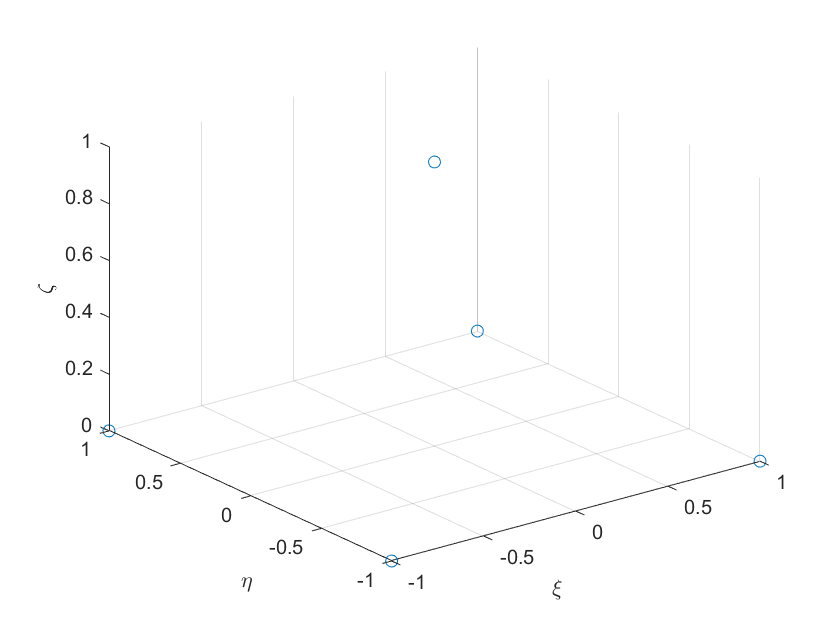

plot3(double(P_Nodes(:,1)),double(P_Nodes(:,2)),double(P_Nodes(:,3)),'o')

set(gca,'XGrid','on','YGrid','on','ZGrid','off')
xlabel('\xi')
ylabel('\eta')
zlabel('\zeta')